N = 5;
% design vector x
% = [torque_Ls, torque_Rs, xs, ys, vs, thetas, thetadots, Tf]
x0 = [zeros(7*N,1); 1];

costfcn = @(x) x(end);

options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'Display', 'iter');

path = [0,0;1,0;1,1;2,1];
xstar = fmincon(costfcn, x0,[],[],[],[],[],[], @(x)nonlcon(x,path), options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      37    1.000000e+00    2.000e+00    5.000e-01
    1      74    8.632077e-01    1.529e+00    5.000e-01    1.318e+00
    2     113    7.338706e-01    1.529e+00    5.000e-01    2.490e-01
    3     152    5.513203e-01    1.528e+00    5.000e-01    4.468e-01
    4     191    4.141794e-01    1.527e+00    5.000e-01    5.330e-01
    5     230    3.111523e-01    1.526e+00    5.000e-01    6.837e-01
    6     269    2.337531e-01    1.524e+00    5.000e-01    9.371e-01
    7     306    1.760642e-01    1.522e+00    5.000e-01    1.671e+00
    8     343    2.120757e-01    7.504e-01    2.053e-02    3.890e+00
    9     381    2.140364e-01    7.501e-01    2.072e-02    1.420e-01
   10     422    5.112835e-01    7.228e-01    5.794e-02    2.999e+00
   11     465    1.128792e+00    5.805e-01    8.945e-02    1.974e+00
   12     502    1.127716e+00    5.799e-01    8

xstar =     0.0099
    0.9477
    2.0423
   -2.9998
   -0.0000
    0.2097
    2.9968
   -2.6555
   -0.5510
   -0.0000


% xstar = it_nonlcon(costfcn, x0, options);

% Extract states from design vectorgit 
[ts, tauL, tauR, x, y, v, th, th_dot] = unpack_design_vector(xstar);
disp(x);

   -0.0000
   -0.0000
    0.0683
    1.3594
    2.0000



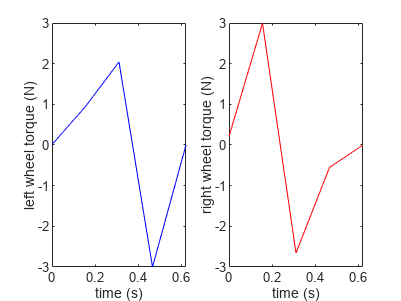


% Plot all states and trajectory
figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

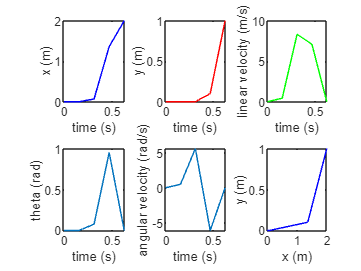


figure
hold on
subplot(2, 3, 1);
plot(ts, x, 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, y, 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, v, 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, th)
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, th_dot)
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(x, y, 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

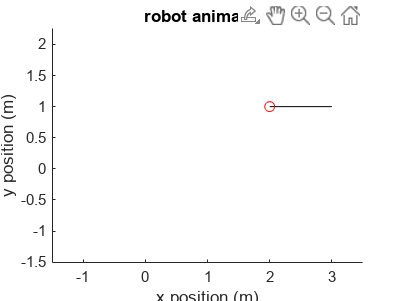


animate_direct_collocation(xstar)